# Estimating recession parameters with the Pareto distribution method

## Introduction

This example demonstrates how to detect recession events, and then estimate recession parameters *a* and *b* using the hybrid Pareto distribution-"point cloud" method (Cooper et al. 2023). Unlike the traditional point-cloud method, the key advantage of this method is that the Pareto distribution identifies "late-time" drainage behavior and provides an estimate of *b* for the late-time regime.

We use daily streamflow data measured in the Kuparuk River Basin on the North Slope of Alaska provided by the United States Geological Survey, recorded at streamflow gage 1596000. The data are included in the |data/| folder as a sample dataset with this toolbox, or can be downloaded from [https://waterdata.usgs.gov/monitoring-location/15896000.](https://waterdata.usgs.gov/monitoring-location/15896000.)

## Preparing data for recession analysis

Set the sitename.

sitename = bfra.basinname('KUPARUK R NR DEADHORSE AK');

Load streamflow data for the test basin into the workspace. In the sample dataset, the variable `T` is *time*, `Q` is *discharge*, and `R` is *rainfall*.

[T, Q, R] = bfra.testdata('example');

Set the basin area and geomorphological parameters.

Dd = 0.8;            % drainage density 
A = 8.6545e9;        % basin area [m2]
L = A*Dd/1000;       % active stream length

## Set options for detecting and fitting recession events

The toolbox supports three main tasks: recession event detection, recession event curve-fitting, and parameter estimation via distribution fitting. The `setopts` function provides an interface to set options for the algorithms that implement these tasks.

Set default algorithm options for `getevents` and `fitevents`.

opts.getevents = bfra.setopts('getevents');
opts.fitevents = bfra.setopts('fitevents');

In addition to `getevents and` `fitevents`, in this example we set options for `globalfit`. The term "globalfit" differentiates two fitting procedures: one that fits individual recession events to estimate parameters specific to each  particular event (which is the purpose of `fitevents`), and another that fits a collection of events to derive a "global" parameter value applicable to the entire sample population (the purpose of `globalfit`).

Set options for `globalfit.`

opts.globalfit = bfra.setopts('globalfit','drainagearea',A,'streamlength',L, ...
   'drainagedensity',Dd,'isflat',true,'plotfits',true);

## Recession analysis workflow

The following steps demonstrate a typical workflow in baseflow recession analysis. The steps consist of getting a list of recession events, fitting the recession events, and then estimating the recession parameters *a* and *b*. 

### Step 1. Get events

EventData = bfra.getevents(T,Q,R,opts.getevents);

### Step 2. Fit events

[EventFits,FitsTable] = bfra.fitevents(EventData,opts.fitevents);

### Step 3. Fit recession parameters *a* and *b*

The `globalfit` function fits a Pareto distribution to the sample population of event-scale parameters stored in `FitsTable`. The parameters of the Pareto distribution $\tau_0$ and $\alpha$ can be related to the traditional recession analysis parameters $a$ and $b$. For details, see Cooper et al. 2023. The value of these parameters are printed on the two figures below. 

The first figure below shows the Pareto complementary cumulative frequency distribution. The Pareto fit provides three parameter estimates: $\tau_0$, $\langle\tau\rangle$, and $\alpha$. Note that $\alpha$ is not shown explicitly, it is expressed in terms of $b$ via the relationship:

$b = 1 + 1/\alpha$.

The second figure shows a traditional recession analysis point cloud diagram, but with one important distinction: the "late-time" drainage regime is indicated by red circles. These values represent discharge events for timescales longer than $\tau_0$, which are the timescales for which the upstream boundary conditions are no longer "felt" at the downstream channel. Similar "early-time" and "late-time" regimes are important in other fluid-flow problems. In the context of baseflow recession analysis, identifying the "late-time" regime is important because the parameters for this regime provide insight into aquifer properties that control late-time drainage. 

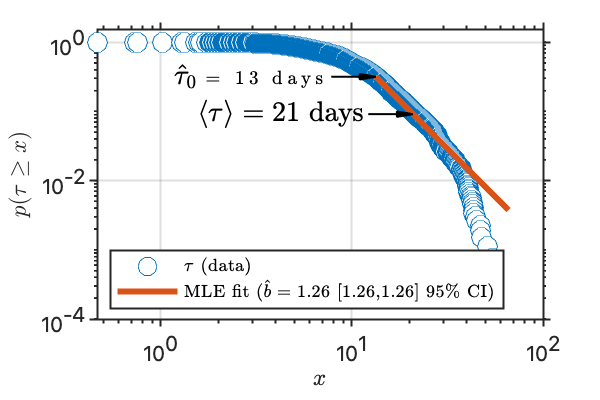

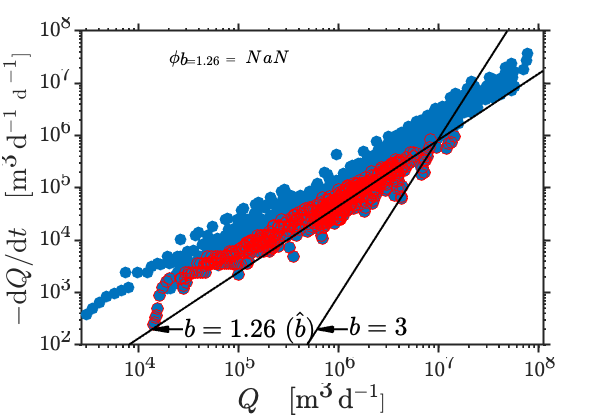

GlobalFit = bfra.globalfit(FitsTable,EventData,EventFits,opts.globalfit);

## Check the fitted recession parameters

The recession parameters *a* and *b* are available in the `GlobalFit` struct.

GlobalFit.a % late-time recession constant in recession equation -dQ/dt = aQ^b

ans =     0.0011672

GlobalFit.b % late-time recession constant in recession equation -dQ/dt = aQ^b

ans =        1.2648

In addition, the `GlobalFit` struct contains the Pareto distribution exponent $\alpha$, the Pareto scale parameter $\tau_0$, the expected value $\langle\tau\rangle$, and more.

## Convert from Pareto notation to recession analysis notation

The toolbox includes a utility function `bfra.conversions` for converting between related quantities. For example, the Pareto distribution exponent $\alpha$ is related to the constant *b* in the traditional recession equation $-dQ/dt = aQ^b$ via the relationship:

$b = 1 + 1/\alpha$.

Use the function to convert from $\alpha$ to $b$.

bfra.conversions(GlobalFit.b,'b','alpha')

ans =        3.7758

Compare that to the value of $\alpha$ in the GlobalFit struct:

GlobalFit.alpha

ans =        3.7758

Like all functions in the toolbox, `bfra.conversions` supports tab-completion. Users are encouraged to explore the conversions supported by this function which provide insight into the relationships between important variables and parameters. The notation follows Cooper et al. 2023.

## References

Cooper M G, Zhou T, Bennett K E, Bolton W R, Coon E T, Fleming S W, Rowland J C and Schwenk J 2023 Detecting Permafrost Active Layer Thickness Change From Nonlinear Baseflow Recession *Water Resources Research* **59** e2022WR033154